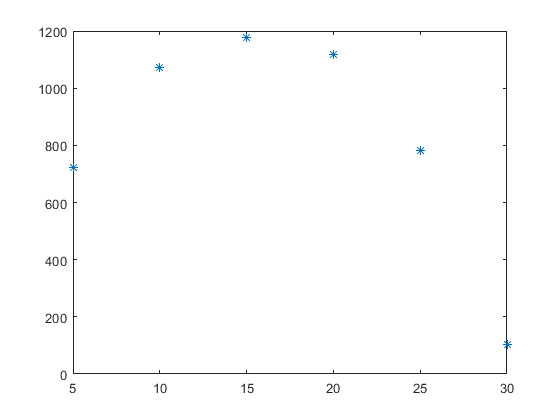

t = [5 10 15 20 25 30];
h = [722 1073 1178 1117 781 102];

plot(t,h,'*');

% Aparatado A
% regresion lineal de matlab
model = fitlm(t,h,'RobustOpts',"off")

model = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE      tStat      pValue 
                   ________    ______    ______    ________

    (Intercept)     1232.5     352.58    3.4958    0.024992
    x1             -23.069     18.107    -1.274     0.27164


Number of observations: 6, Error degrees of freedom: 4
Root Mean Squared Error: 379
R-squared: 0.289,  Adjusted R-Squared: 0.111
F-statistic vs. constant model: 1.62, p-value = 0.272

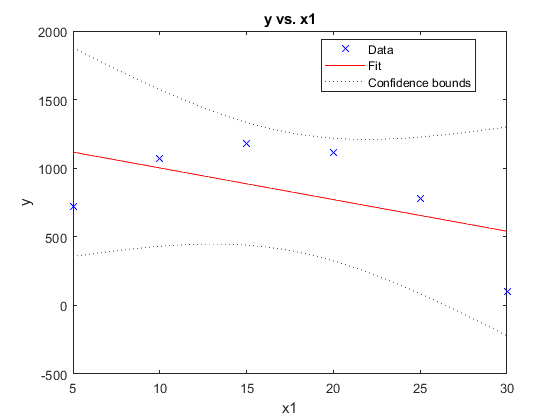

plot(model);

recta = @(x) -23.069.*x + 1232.5;

residuos = recta(t)' - h';
norm(residuos, 2)

ans =        757.46



% Apartado B
A = [(t.^2)', t', ones(size(t'))];
coeff = A\h'

coeff =       -4.9386
       149.78
         80.2


pol = polyval(coeff, linspace(0,30));
y = polyval(coeff, t')

y =        705.64
       1084.2
       1215.7
       1100.4
       738.13
       128.93


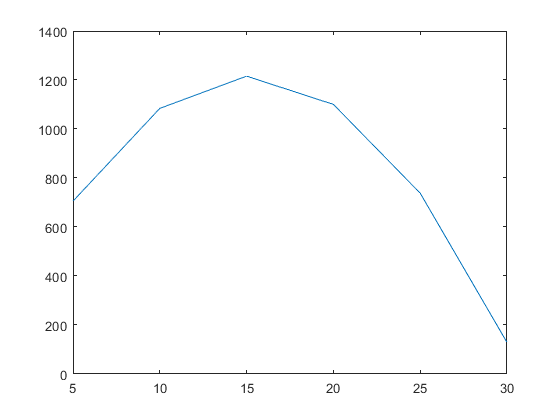

plot(t, y);  % where a is coefficients of a polynomial

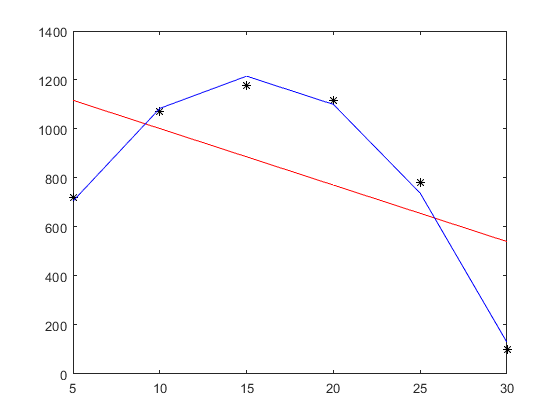

recta = @(x) -23.069.*x + 1232.5;
parabola = @(x) -4.9386.*x.^2 + 149.78.*x + 80.2;

y1 = recta(t);
y2 = parabola(t);
plot(t,h,'black*',t,y1,'-r',t,y2,'-b')